# **ACM 11 Homework 1 Part 2/2 (Spring 2024)**

## **Due Friday, April 12, 11:59pm Pacific Time, by upload to Canvas.**

This portion of the assignment is worth $25$ points. 

Parts **a), b), c) **are theoretical questions that will involve showing your work. You may submit answers to these parts through the following methods:

- You may write in this `MATLAB` script directly underneath the questions.

- You may work on your iPad, paper or LaTeX, and attached the .pdf in your Canvas Submission. 

Part **d)** is an implementation question and will involve writing code from scratch. 

### **Problem 6 (Properties of Forward Euler, 25 points)**

In lecture $1$, we discussed how to use the forward Euler method to numerically approximate the solution for complicated ODEs where it is often not possible to obtain a closed-form solution. However, it might be useful to observe the theoretical properties held by the Forward Euler method on a simple ODE by comparing the approximation to the true solution. Consider the linear ODE:


$$$$\frac{d\phi}{dt} = 2t$$$$


Let $\phi$ be the solution to the ODE above, with the initial condition that $\phi(0) = 0$.

**(5 points) **What is the true solution $\phi(1)$ using the analytical solution for $\phi(t)$?

Answer for A-C are attached in a pdf along with this.

`(answer attached in pdf)`

**(5 points) **Write the forward Euler approximation for $\phi(1)$ using $2$ steps of equal length beteen $t = 0$ and $t=1$. Write it also for $3$ steps of equal length.

`(answer attached in pdf)`

**(5 points) **Write the forward Euler approximation for $\phi(1)$ using $n$ steps of equal length, for any natural number $n$. Does the forward Euler approximation converge to $\phi(1)$ as $n \rightarrow \infty$? Explain why or why not by deriving the absolute error between the approximate solution and the true solution for $\phi$ at $t = 1$.

`(attached in pdf)`

**(10 points) **Implement the forward Euler approximation for the ODE and generate two plots: 

- The value of the forward Euler approximation against time on the interval $[0,1]$ for $n = \{4,16,64,256\}$ steps. For the plot, you only need to evaluate the approximation at the grid points defined by discretizing the interval.

- The absolute error between the forward Euler approximation and the true solution $\phi(t)$ against time on the interval $[0,1]$ using $n = \{4,16,64,256\}$ steps.

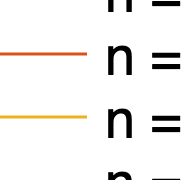

phi_true = @(t) t.^2;
f = @(t) 2.*t;
n_values = [4, 16, 64, 256];

figure;
hold on;
figure;
hold on;

for n = n_values
    h = 1/n;
    t = 0:h:1;
    phi_approx = zeros(1, n+1);
    
    for i = 1:n
        phi_approx(i+1) = phi_approx(i) + h*f(t(i));
    end
    
    figure(1);
    plot(t, phi_approx, 'DisplayName', ['n = ' num2str(n)]);
    
    figure(2);
    abs_error = abs(phi_true(t) - phi_approx);
    plot(t, abs_error, 'DisplayName', ['n = ' num2str(n)]);
end

figure(1);
title('Forward Euler Approximation ');
xlabel('Time (t)');
ylabel('Approximation of \phi(t)');
legend('Location', 'Best');
grid on;


figure(2);
title('Absolute Error');
xlabel('Time (t)');
ylabel('Absolute Error');
legend('Location', 'Best');
grid on;

Explain (in a paragraph) why the derivations done in **a) - c)** agree with the plots generated in **d)**.

The derivations from parts a) to c) establish the groundwork that supports the numerical and graphics; observations made in part d). In part a), we found the true solution *ϕ*(*t*)=*t^2 *of the given differential equation, setting a reference point for evaluating the accuracy of numerical approximations. In Part b) we applied the Forward Euler method with a fixed number of steps, showing how the method steps through time to approximate *ϕ*(*t*) at *t*=1, thus giving us the iterative nature of the Euler method. In Part c), we analysed the convergence of the Forward Euler approximation to the true solution as *n*→∞, showing the inverse relationship between the number of steps and the absolute error. This theoretical basis directly aligns with the outcomes we see in the plots generated in part d), where the Forward Euler approximations for increasing values of *n*(*n*=4, 16, 64, 256) shower a clear trend towards greater accuracy (lower absolute error) in approximating the true solution *ϕ*(*t*) over the interval [0,1]. The plots are a visual confirmation of the convergence behavior we discussed in part c), with the approximation's accuracy improving as the step size decreases (i.e., as *n *increases).